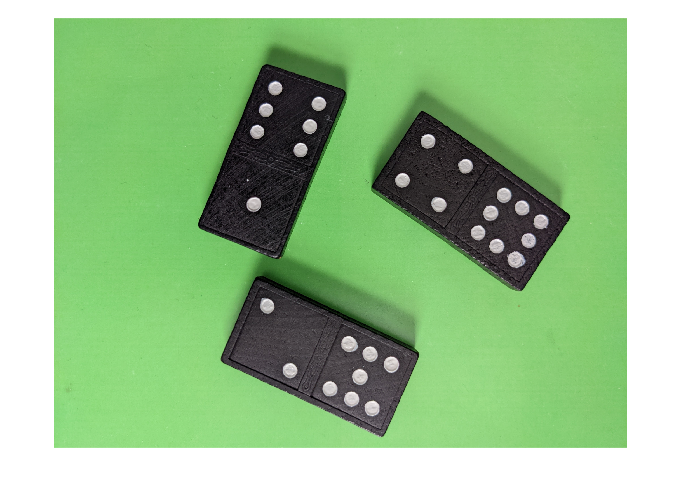

a= imread('dominos.jpg');
imshow(a)

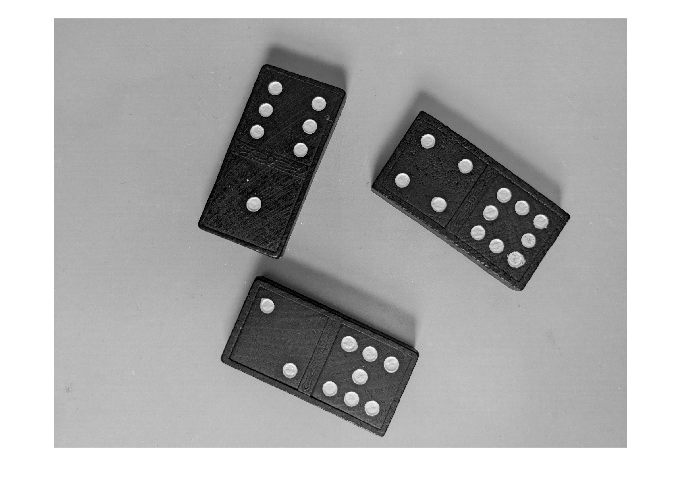

a2= im2gray(a);
imshow(a2)

points= detectSURFFeatures(a2)

points =   1804×1 SURFPoints array with properties:

              Scale: [1804×1 single]
    SignOfLaplacian: [1804×1 int8]
        Orientation: [1804×1 single]
           Location: [1804×2 single]
             Metric: [1804×1 single]
              Count: 1804


points.Scale

ans = 1804×1 single column vector
    4.0000
    2.2667
    4.4000
    2.8000
    2.0000
    2.6667
    2.6667
    2.9333
    2.5333
    2.8000


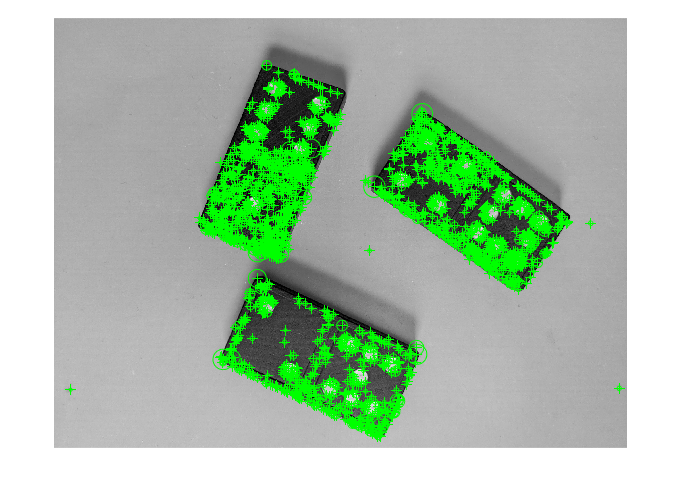

imshow(a2)
hold on
plot(points)
hold off

imshow(a2)
hold on
strong_points= selectStrongest(points,100)

strong_points =   100×1 SURFPoints array with properties:

              Scale: [100×1 single]
    SignOfLaplacian: [100×1 int8]
        Orientation: [100×1 single]
           Location: [100×2 single]
             Metric: [100×1 single]
              Count: 100


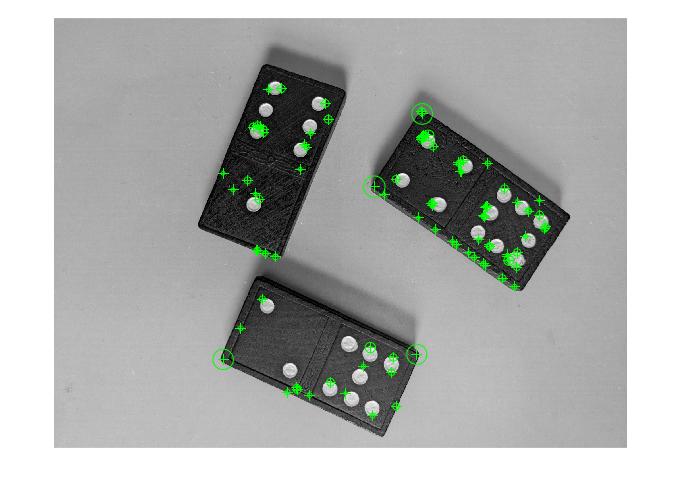

plot(strong_points)
hold off

% larger blobs
points2= detectSURFFeatures(a2,"NumOctaves",5)

points2 =   1918×1 SURFPoints array with properties:

              Scale: [1918×1 single]
    SignOfLaplacian: [1918×1 int8]
        Orientation: [1918×1 single]
           Location: [1918×2 single]
             Metric: [1918×1 single]
              Count: 1918


imshow(a2)
hold on
strong_points= selectStrongest(points2,100)

strong_points =   100×1 SURFPoints array with properties:

              Scale: [100×1 single]
    SignOfLaplacian: [100×1 int8]
        Orientation: [100×1 single]
           Location: [100×2 single]
             Metric: [100×1 single]
              Count: 100


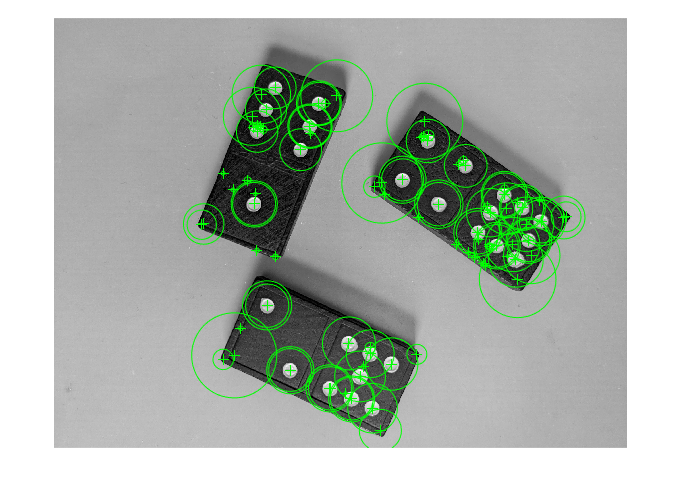

plot(strong_points)
hold off

imshow(a2)
hold on
strong_points= selectStrongest(points2,20)

strong_points =   20×1 SURFPoints array with properties:

              Scale: [20×1 single]
    SignOfLaplacian: [20×1 int8]
        Orientation: [20×1 single]
           Location: [20×2 single]
             Metric: [20×1 single]
              Count: 20


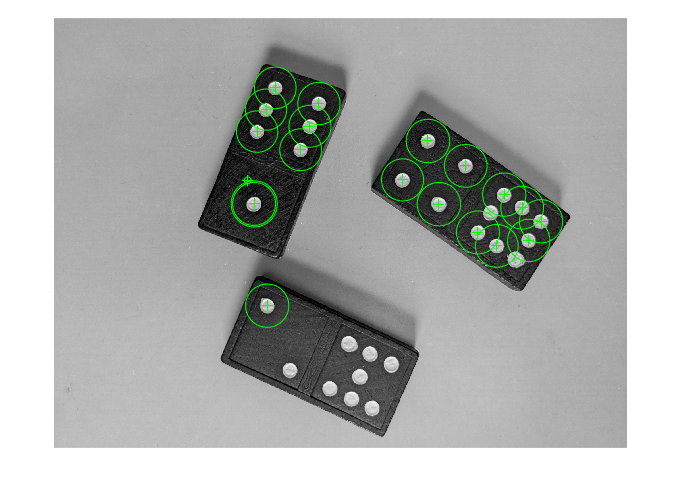

plot(strong_points)
hold off